clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings
LUCopper = [147, 86, 14]/255;LUCopper_Light = [225, 213, 199]/255;LUBlue = [17, 55, 125]/255;LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;Red_Light = [235, 200, 197]/255;pink = [255, 199, 206]/255;skyblue_light=[183/255 236/255 255/255];

## Load or Define Pressure-Time Data


load('E2038.mat');  % Load dataset
testNum = 3;
p_original = (p(:,testNum) - mean(p(1:100,testNum))) * 1000; %[mbar] % Mean subtraction
Fs = fs;  % Sampling frequency in Hz
t = (0:length(p_original)-1)'/Fs;  % Time vector

%% Compute Original Parameters
E_original = sum(abs(p_original).^2);  % Total energy
Impulse_original = trapz(t, p_original);  % Impulse calculation
Impulse_original_check = cumtrapz(t, p_original);
Icheck_original = (Impulse_original_check(end)/Impulse_original) * 100;
% figure;
% plot(t, Impulse_original_check);  % Should show a smooth increasing function
% hold off
% PeakPressure_original = max(p_original);  % Peak pressure
[PeakPressure_original, idx] = max(p_original, [], 1); % Peak pressure
PeakPressure_original_T = t(idx); % [s]

## Define Cutoff Frequencies & Filter Orders to Test 

### Perform Empirical Wavelet Transform (EWT)

MaxNumPeaks = 25; % Set max number of peaks for adaptive segmentation
% MaxNumPeaks = 5; % Set max number of peaks for adaptive segmentation
[mra, cfs, wfb, info] = ewt(p_original, 'MaxNumPeaks', MaxNumPeaks);
% [mra, cfs, wfb, info] = ewt(p_original,'PeakThresholdPercent',2);

#### Extract Peak Frequencies and Passbands

PeakFrequencies = Fs * info.PeakFrequencies;
freqPassbands = Fs * info.FilterBank.Passbands;
% cutoff_frequencies = linspace(100, 2000, 10);  % Test 10 different cutoff frequencies
cutoff_frequencies = PeakFrequencies;  % Test 10 different cutoff frequencies
n = zeros(size(cutoff_frequencies,1),1);
% cutoff_frequencies = 250:150:1000;
for i = 1:length(cutoff_frequencies)
    % Given parameters
    fc = cutoff_frequencies(i);   % Passband cutoff frequency (Hz)
    fs_stop = cutoff_frequencies(i) + 500; % Stopband frequency (Hz)
    Rp = 3;      % Maximum ripple in passband (dB)
    Rs = 40;     % Minimum stopband attenuation (dB)

    % Normalize frequencies to Nyquist frequency (Fs/2)
    Wp = fc / (Fs/2);
    Ws = fs_stop / (Fs/2);

    % Compute minimum Butterworth filter order
    n(i) = buttord(Wp, Ws, Rp, Rs);
end
nMin = max(n);
filter_orders = [nMin, nMin + 2, nMin + 4, nMin + 6];  % Filter orders


## Matrices to store results

% Memory Allocation
energy_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
impulse_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_T_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));

%% Apply Low-Pass Filtering for Different Cutoff Frequencies & Orders
for f_idx = 1:length(filter_orders)
    for c_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(c_idx);  % Current cutoff frequency
        filter_order = filter_orders(f_idx);  % Current filter order
        lpFilt = designfilt('lowpassiir', ...
        'FilterOrder', filter_order, ...
        'HalfPowerFrequency', fc, ...
         'DesignMethod','butter',...
        'SampleRate', Fs);
        % Zero-phase filtering
        p_filtered = filtfilt(lpFilt, p_original);
        % Compute energy, impulse, and peak pressure after filtering
        E_filtered = sum(abs(p_filtered).^2);
        Impulse_filtered = trapz(t, p_filtered);
        % PeakPressure_filtered = max(p_filtered);
        [PeakPressure_filtered, idx] = max(p_filtered, [], 1); 
        PeakPressure_filtered_T = t(idx); % [ms]

        % Store results as ratio (%)
        energy_ratio_matrix(f_idx, c_idx) = (E_filtered / E_original) * 100;
        impulse_ratio_matrix(f_idx, c_idx) = (Impulse_filtered / Impulse_original) * 100;
        peak_pressure_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered / PeakPressure_original) * 100;
        % peak_pressure_T_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered_T / PeakPressure_original_T) * 100;
    end
end


## Plot Results: Low-Pass Filter Order & Cuttoff Frequency Analysis

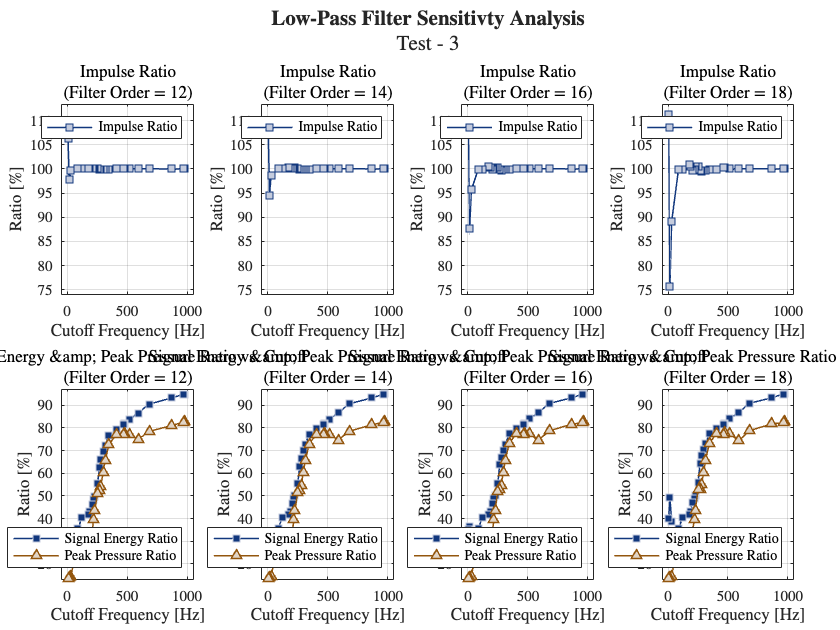

figure;
tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact'); % Define 2 rows, 4 columns

for f_idx = 1:length(filter_orders)
    % Top row: Impulse Ratio
    nexttile(f_idx); % Assigns first 4 tiles for impulse ratio
    plot(cutoff_frequencies, impulse_ratio_matrix(f_idx, :), '-s','Color',LUBlue,'MarkerFaceColor',LUBlue_Light,'MarkerEdgeColor',LUBlue, 'LineWidth', 1);
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    % xlim([-10 max(cutoff_frequencies) * 1.05]);
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min(impulse_ratio_matrix(:, :))) * 0.98, max(max(impulse_ratio_matrix(:, :))) * 1.02]); % Adds slight margin
    % ylim([75 115]); % Adds slight margin
    title({'Impulse Ratio',['(Filter Order = ' num2str(filter_orders(f_idx)) ')']},'Interpreter', 'latex');
    legend('Impulse Ratio', 'Location', 'northeast', 'Interpreter', 'latex');
    grid on;

    % Bottom row: Energy Ratio & Peak Pressure Ratio
    nexttile(f_idx + 4); % Assigns tiles 5-8 for energy/pressure ratio
    plot(cutoff_frequencies, energy_ratio_matrix(f_idx, :), '-s','Color',LUBlue,'MarkerFaceColor',LUBlue,'MarkerEdgeColor',LUBlue_Light, 'LineWidth', 1); hold on;
    plot(cutoff_frequencies, peak_pressure_ratio_matrix(f_idx, :), '-^','Color',LUCopper,'MarkerEdgeColor',LUCopper,'MarkerFaceColor',LUCopper_Light, 'LineWidth', 1);hold on;

    % plot(cutoff_frequencies, peak_pressure_T_ratio_matrix(f_idx, :), ':v','Color',LUCopper,'MarkerEdgeColor',LUCopper_Light,'MarkerFaceColor',LUCopper, 'LineWidth', 1);
    hold off;
    
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    % xlim([0 max(cutoff_frequencies) * 1.02]);
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 0.98 max(max([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 1.02]); % More generous spacing
    title({'Signal Energy \& Peak Pressure Ratio vs. Cutoff',[' (Filter Order = ', num2str(filter_orders(f_idx)), ')']},'Interpreter', 'latex');
    % legend('Signal Energy Ratio', 'Peak Pressure Ratio','Peak Pressure Time Shift Ratio', 'Location', 'southeast', 'Interpreter', 'latex');
    legend('Signal Energy Ratio', 'Peak Pressure Ratio','Location', 'southeast', 'Interpreter', 'latex');
    grid on;
end
sgtitle({'\textbf{Low-Pass Filter Sensitivty Analysis}',sprintf('Test -  %d', testNum)},'fontsize',14, 'Interpreter', 'latex')

hold off;